clear all; close all; clc;

%% Filter Design
% Parameters
Nbranches = 4;             % Number of branches in the polyphase filter
Ntaps = 4;                 % Number of taps per filter branch
N = Nbranches*Ntaps;
Tsample = 1;                % Sampling time
BP = 1/Tsample;             % Bandwidth
chann_w = BP/Nbranches;     % Channel width for each branch
filter_chunk = Nbranches;
n = 0:N-1;
center = n - (N-1)/2;       % Centers filter coefficients for output (i.e. 1,16 -> -8,8)

% Sinc Function
sinc_function = zeros(1, N);
for i = 1:N
    if center(i) == 0
        sinc_function(i) = 2*chann_w;
    else
        sinc_function(i) = sin(2*pi*chann_w*Tsample*center(i)) / (pi*Tsample*center(i));
    end
end

% Generate Hanning Window
hann = 0.5 - 0.5*cos(2*pi*n/(N-1));

% Create Final Filter and Normalize
filter = sinc_function .* hann;
normal_filter = filter/max(filter(:))

normal_filter =          0   -0.0034    0.0152    0.0388   -0.0798   -0.1517    0.3048    1.0000    1.0000    0.3048   -0.1517   -0.0798    0.0388    0.0152   -0.0034         0


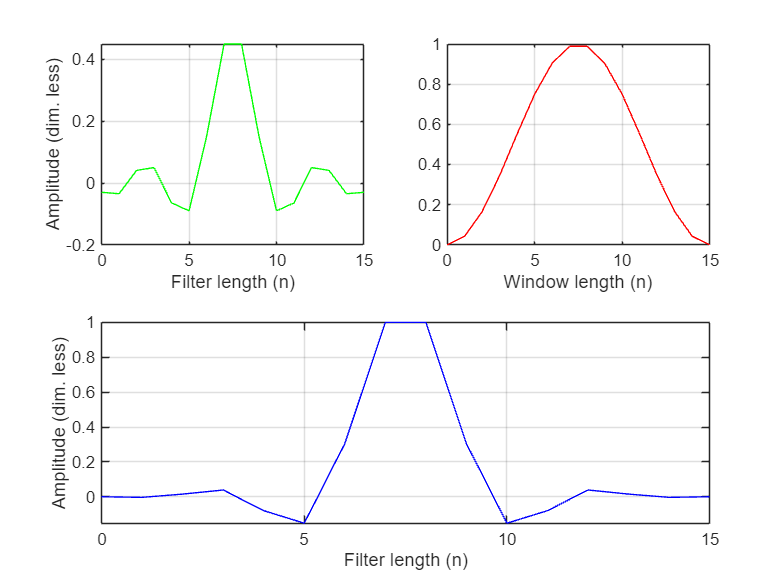


% Display Outputs
subplot(2,2,1);
plot(n, sinc_function, 'g');
grid on;
xlabel('Filter length (n)');
ylabel('Amplitude (dim. less)');

subplot(2,2,2)
plot(n, hann, 'r');
xlabel('Window length (n)')
grid on;

subplot(2,2,[3,4])
plot(n, normal_filter, 'b');
xlabel('Filter length (n)')
ylabel('Amplitude (dim. less)')
grid on;


%% Input Signal Generation
clear length
N_filter = length(normal_filter);

% Generate test input signal
fs = 100;
T = N_filter/fs;
t = (0:(N_filter*4)-1);            % Time vector (For signal generation and later graphing)

f1 = 0.1;
input_signal = sin(2*pi*f1*t) %+ 0.1*randn(size(t))

input_signal =          0    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878


## DFT/IDFT matricies

%2d fft
N_dft = filter_chunk;
W = zeros(N_dft, N_dft);

for k = 0:N_dft-1
    for n = 0:N_dft-1
        W(k+1, n+1) = exp(-2*pi*1j*k*n/N_dft);
    end
end

%2d ifft
W_inv = zeros(N_dft, N_dft);

for n = 0:N_dft-1
    for k = 0:N_dft-1
        W_inv(n+1, k+1) = (1/N_dft) * exp(2*pi*1j*k*n/N_dft);
    end
end

## PFB Forwards

% Parameters + Pre-allocation
num_full_blocks = floor(length(input_signal) / filter_chunk);               
mat_its = floor((length(input_signal) - N_filter) / filter_chunk) + 1;      
stored_matrix = cell(mat_its, 1);                                           
stored_fft_blocks = cell(mat_its, 1);                                       
output_cols = ((mat_its-1) * filter_chunk) + N_filter;                        
output_mat = zeros(mat_its * filter_chunk, output_cols);                    

% Main analysis loop - process input signal in blocks
for j = 1:mat_its
    % Initialize matrix for current iteration
    matrix = zeros(filter_chunk, N_filter);
    startpoint = (j-1) * filter_chunk + 1;
    blockend = startpoint + N_filter - 1;
    values = startpoint:blockend;
    
    % Apply filter to input segment
    Y = input_signal(values) .* normal_filter;    
    
    % Fill matrix with filtered values in polyphase arrangement
    for i = 1:N_filter
        matrix(mod(i-1, filter_chunk) + 1, i) = Y(i);
    end 
    stored_matrix{j} = matrix;

    % Place matrix block into overall output matrix
    row_start = (j-1) * filter_chunk + 1;
    row_end = j * filter_chunk;
    col_start = (j-1) * filter_chunk + 1;
    col_end = col_start + N_filter - 1;   
    if col_end <= output_cols
        output_mat(row_start:row_end, col_start:col_end) = stored_matrix{j};
    end
end
disp(output_mat)

         0         0         0         0   -0.0469         0         0         0   -0.9511         0         0         0    0.0369         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0020         0         0         0   -0.0000         0         0         0   -0.1792         0         0         0    0.0145         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

size(output_mat)

ans =     52    64


## DFT

% Initialize FFT output matrix
fft_matrix = zeros(mat_its*filter_chunk, mat_its*filter_chunk);

% Apply matrix-based 2D DFT to each stored matrix block
for i = 1:mat_its
   polyphase_samples = sum(stored_matrix{i}, 2);  % Sum across taps (column vector)
   freq_samples = polyphase_samples.*W;
    
    % Reshape back to 2D block
    stored_fft_blocks{i} = freq_samples;

    % Place FFT block into overall FFT matrix
    blockstart = (i-1)*filter_chunk + 1;
    blockend = i*filter_chunk;
    fft_matrix(blockstart:blockend, blockstart:blockend) = freq_samples;
end

disp(fft_matrix)

  -0.9610 + 0.0000i  -0.9610 + 0.0000i  -0.9610 + 0.0000i  -0.9610 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.1667 +

real(fft_matrix)

ans =    -0.9610   -0.9610   -0.9610   -0.9610         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.1667   -0.0000    0.1667    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

imag(fft_matrix)

ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.1667    0.0000   -0.1667         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

## Signal reconstruction

%% Extract Xk[m] from fft_matrix structure
% Each block is PxP
% The diagonal of each block contains the K frequency channel values

K = filter_chunk;
M = K;  % Decimation/interpolation factor

% Initialize output signal
output_length = length(input_signal) + N_filter;
reconostructed_signal = zeros(1, output_length);

% Synthesis filter (for perfect reconstruction, typically same as analysis)
synthesis_filter = normal_filter;

% Process each time block m
for m = 1:mat_its
    blockstart = (m-1)*K + 1;
    blockend = m*K;
    
    % Get the m-th diagonal block from fft_matrix
    freq_block = fft_matrix(blockstart:blockend, blockstart:blockend);
    
    % Directly perform IFFT on each column of freq_block
    % Resulting time_samples will be K x K
    time_samples_block = freq_block.*W_inv;  % IFFT along columns by default
    
    % Upsample and overlap-add each column
    for col = 1:K
        time_samples = diag(time_samples_block);  % diagonal of time samples
        
        % Zero-pad for upsampling
        upsampled_length = K * M;
        upsampled = zeros(1, upsampled_length);
        upsampled(1:M:end) = time_samples;
        
        % Convolve with synthesis filter
        filtered = conv(upsampled, synthesis_filter);
        
        % Time shifting for overlap-add
        time_shift = (m-1) * M;  % zero-based
        output_start = time_shift + 1;
        output_end = min(output_start + length(filtered) - 1, output_length);
        valid_length = output_end - output_start + 1;
        
        % Overlap-add into reconstructed signal
        reconostructed_signal(output_start:output_end) = ...
            reconostructed_signal(output_start:output_end) + real(filtered(1:valid_length));
    end
end

% Trim to input signal length
reconostructed_signal = reconostructed_signal(1:length(input_signal));

%% Normalize output
input_rms = rms(input_signal);
reconstructed_rms = rms(reconostructed_signal);

gain_correction = input_rms / reconstructed_rms;
reconostructed_signal = reconostructed_signal * gain_correction;

RealPart = reconostructed_signal

RealPart =          0    0.0026   -0.0119   -0.0303    0.0623    0.1161   -0.2277   -0.7544   -0.8350   -0.3399    0.3200    0.7279    0.6802    0.2568   -0.2333   -0.4771   -0.2606    0.0639   -0.2724   -1.0600   -1.2727   -0.5656    0.5890    1.4623    1.4623    0.5862   -0.5532   -1.2410   -1.1250   -0.3953    0.3089    0.5457    0.3581    0.0534    0.0534    0.3581    0.5457    0.3089   -0.3953   -1.1250   -1.2410   -0.5532    0.5862    1.4623    1.4623    0.5862   -0.5532   -1.2410   -1.1250   -0.3953


input_signal

input_signal =          0    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878   -0.0000    0.5878    0.9511    0.9511    0.5878    0.0000   -0.5878   -0.9511   -0.9511   -0.5878



% Calculate reconstruction error
max_error = max(abs(input_signal - reconostructed_signal));
rms_error = rms(input_signal - reconostructed_signal);
relative_error = rms_error / input_rms * 100;

fprintf('\n=== Error Metrics ===\n');


=== Error Metrics ===


fprintf('Maximum absolute error: %.6f\n', max_error);

Maximum absolute error: 1.272669


fprintf('RMS error: %.6f\n', rms_error);

RMS error: 0.668811


fprintf('Relative error: %.4f%%\n', relative_error);

Relative error: 94.3567%



SNR_dB = 20 * log10(input_rms / reconstructed_rms)

SNR_dB = -1.8042

% Create polyphase components
num_polyphase_taps = N/K;
analysis_polyphase = zeros(1, num_polyphase_taps);
synthesis_polyphase = zeros(1, num_polyphase_taps);

for k = 0:K-1
    analysis_polyphase(k+1, :) = normal_filter(k+1:K:end);
    synthesis_polyphase(k+1, :) = synthesis_filter(k+1:K:end);
end

% Check condition: sum_m fm[n] * hm[-n]
PR_check = zeros(1, 2*num_polyphase_taps - 1);
for m = 1:K
    PR_check = PR_check + conv(synthesis_polyphase(m, :), fliplr(analysis_polyphase(m, :)));
end
PR_check

PR_check =    -0.0001   -0.0129   -0.1641    2.2481   -0.1641   -0.0129   -0.0001



% Normalize and analyze
[peak_val, peak_idx] = max(abs(PR_check))

peak_val = 2.2481

peak_idx = 4

PR_normalized = PR_check / peak_val

PR_normalized =    -0.0000   -0.0057   -0.0730    1.0000   -0.0730   -0.0057   -0.0000


sidelobe_energy = sum(abs(PR_normalized).^2) - abs(PR_normalized(peak_idx))^2

sidelobe_energy = 0.0107

## Visualisation

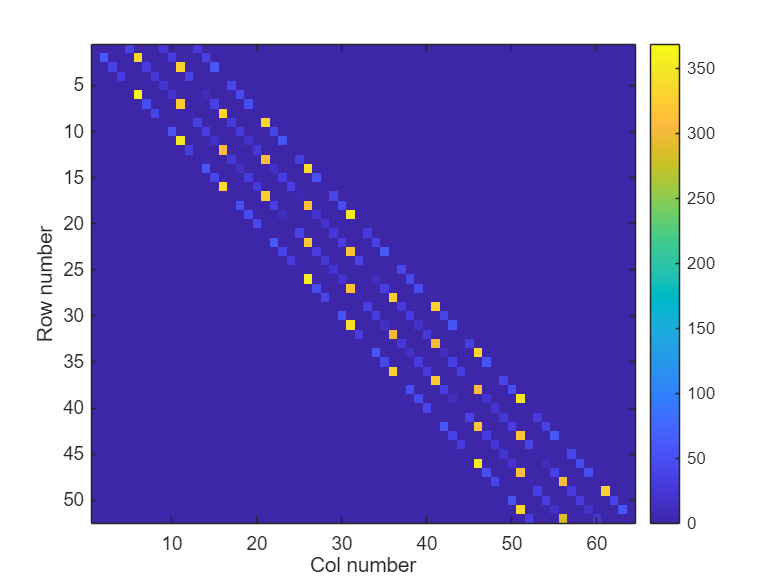

% Convolution Matrix Visualization
logforgraph = abs(20*log10(output_mat));
[r,c] = size(logforgraph);
for i = 1:r
    for j = 1:c
        if logforgraph(i,j) == Inf
            logforgraph(i,j) = 0;
        end
    end
end

% Display convolution matrix as heatmap
figure;
imagesc(logforgraph);
colormap('parula');
colorbar;
xlabel('Col number')
ylabel('Row number')

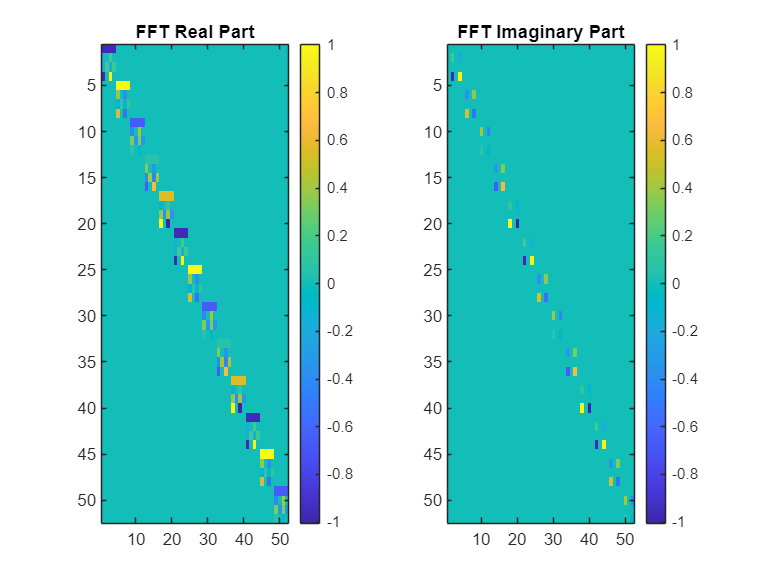


% FFT Matrix Visualization
figure;
subplot(1,2,1);
imagesc(real(fft_matrix));
colormap('parula');
colorbar;
title('FFT Real Part');

subplot(1,2,2);
imagesc(imag(fft_matrix));
colormap('parula');
colorbar;
title('FFT Imaginary Part');


% subplot(2,2,3);
% imagesc(abs(fft_matrix));
% colormap('parula');
% colorbar;
% title('FFT Magnitude');


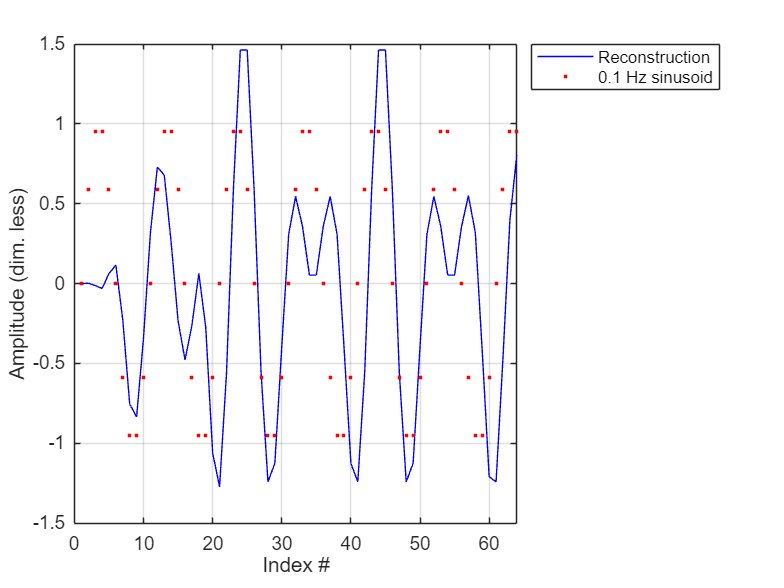

% Reconstructed signal with original overlay
figure;
plot(1:length(RealPart), RealPart, 'b-');
hold on;
plot(1:length(input_signal), input_signal, 'r.');
xlabel('Index #')
ylabel('Amplitude (dim. less)')
legend('Reconstruction', '0.1 Hz sinusoid', 'Location', 'northeastoutside');
grid on;

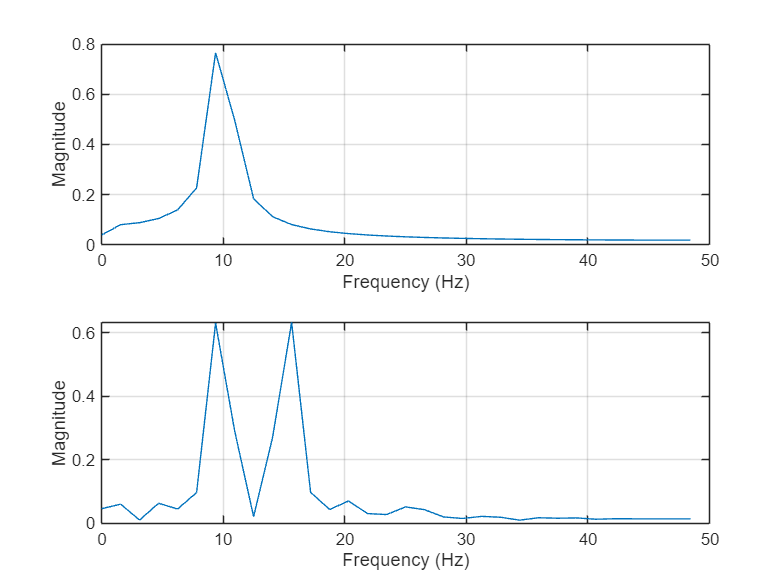


% Frequency response - input signal
N = length(input_signal);
X = fft(input_signal);
X_mag = abs(X)/N;
X_mag(2:end-1) = 2*X_mag(2:end-1);
freq = (0:N-1)*fs/N;

% Frequency response - original and reconstructed signal
N = length(reconostructed_signal);
R = fft(reconostructed_signal);
R_mag = abs(R)/N;
R_mag(2:end-1) = 2*R_mag(2:end-1);

figure;
subplot(2,1,1)
plot(freq(1:N/2), X_mag(1:N/2));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

subplot(2,1,2)
plot(freq(1:N/2), R_mag(1:N/2));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;